Constants

clearvars;
num_symbols = 32*1024; 
symbol_rate = 32e9;
time_step = 1/symbol_rate;
upsampling = 2;
sample_rate = upsampling*symbol_rate;
num_samples = upsampling*num_symbols;
Ts = 1/sample_rate;
rng(1960);

symbols_q = randi([0 3],1,num_symbols);
symbols_16 = randi([0 15],1,num_symbols);

Modulation & Upsampling

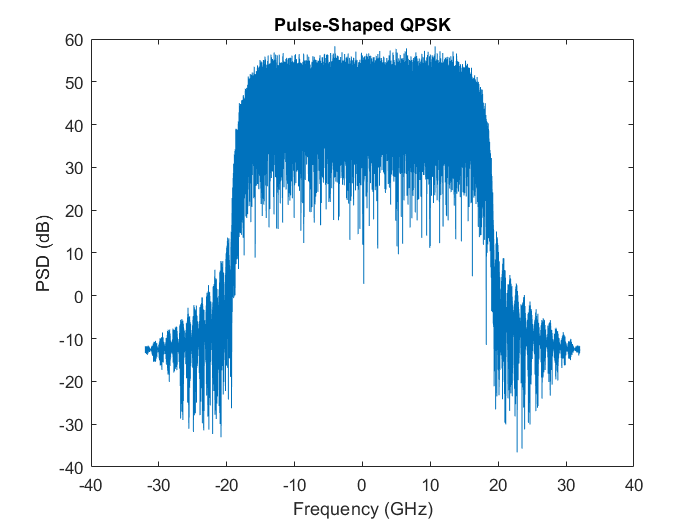

%QPSK
qpsk_mod = pskmod(symbols_q,4,pi/4,'gray');
qam16_mod = qammod(symbols_16,16);

UPS_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",32,"OutputSamplesPerSymbol",upsampling);
DPS_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",32,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling/2);

upsampled_qpsk = UPS_filter(qpsk_mod.').';
upsampled_qam16 = UPS_filter(qam16_mod.').';

Pxx = ifftshift(fft(upsampled_qpsk).*conj(fft(upsampled_qpsk)));
[~,f] = periodogram(upsampled_qpsk,[],[],sample_rate,'centered');
figure
plot(f/1e9,10*log10(Pxx));
xlabel("Frequency (GHz)");
ylabel("PSD (dB)");
title("Pulse-Shaped QPSK");

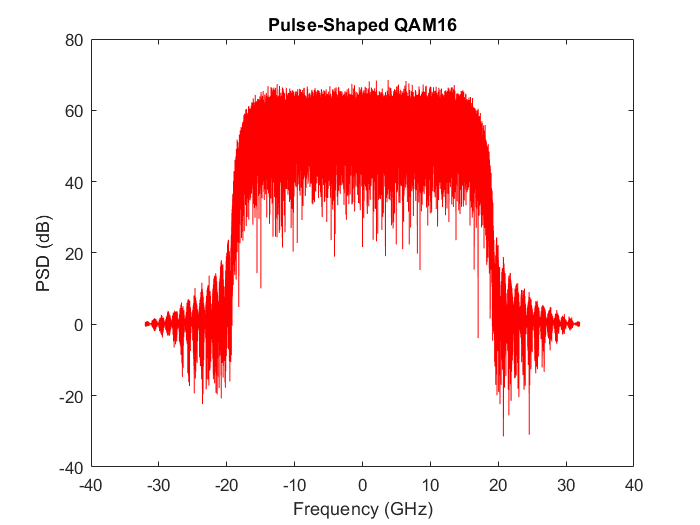


Pxx = ifftshift(fft(upsampled_qam16).*conj(fft(upsampled_qam16)));
[~,f] = periodogram(upsampled_qam16,[],[],sample_rate,'centered');
figure
plot(f/1e9,10*log10(Pxx),"Color",'r');
xlabel("Frequency (GHz)");
ylabel("PSD (dB)");
title("Pulse-Shaped QAM16");


% matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% 
% matched_scope(bpsk_mod',qpsk_mod');
% raised_cosine_scope(upsampled_bpsk',upsampled_qpsk');

Phase Noise

linewidth = 0;
variance = 2*pi*linewidth*Ts;    
phase_noise = randn(1,num_samples);
    
random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
          
noisy_qpsk = upsampled_qpsk.*exp(1j*random_walk_phase_noise);

Chromatic Dispersion

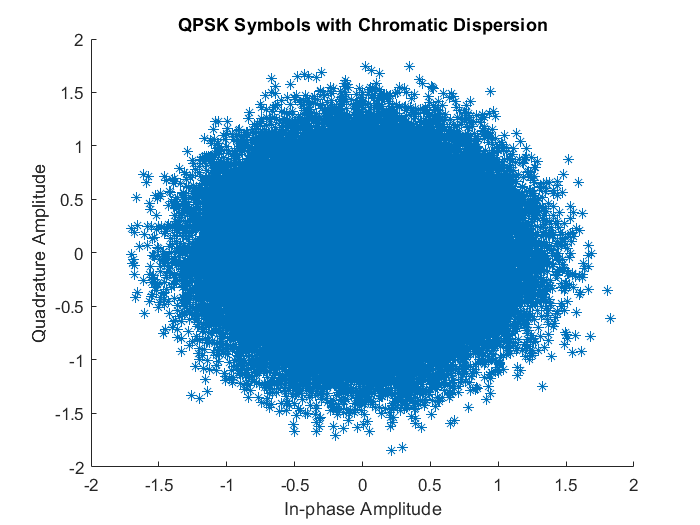

%Define angular frequency vector
 
f_up = (0:(num_samples)/2-1);
f_down = (-(num_samples)/2:-1);
fs = [f_up f_down]*symbol_rate/num_symbols;
w = 2*pi*fs;
 
%Define Chromatic Dispersion Typical Parameters
z = 50e3; % m
D = 16*10^-6; % s/m/m
lambda = 1550*10^-9; % m
c = 299792458; % m/s
beta_2 = -lambda*lambda*D/(2*pi*c);

chromatic_dispersion_FIR = exp(-1j*beta_2/2*(w.^2)*z);

CD_qpsk = ifft(chromatic_dispersion_FIR.*fft(upsampled_qpsk)); 
CD_qam = ifft(chromatic_dispersion_FIR.*fft(upsampled_qam16));

figure
scatter(real(CD_qpsk),imag(CD_qpsk),'*');
title("QPSK Symbols with Chromatic Dispersion");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

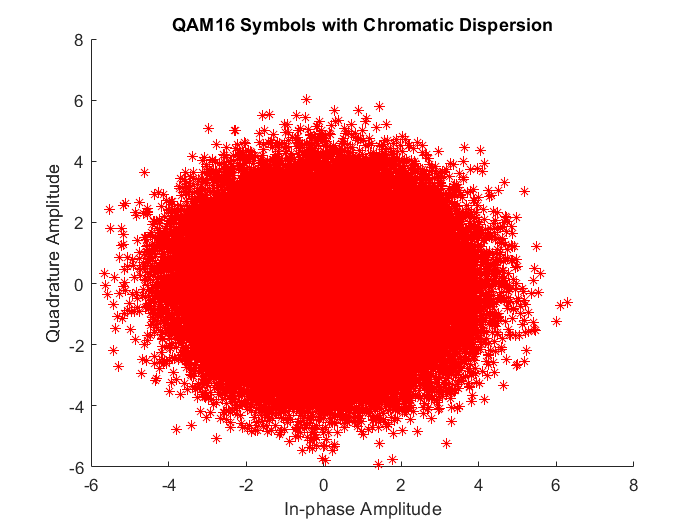


figure
scatter(real(CD_qam),imag(CD_qam),'r*');
title("QAM16 Symbols with Chromatic Dispersion");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

## Adaptive Equalisation (Attempt CMA algorithm) QPSK

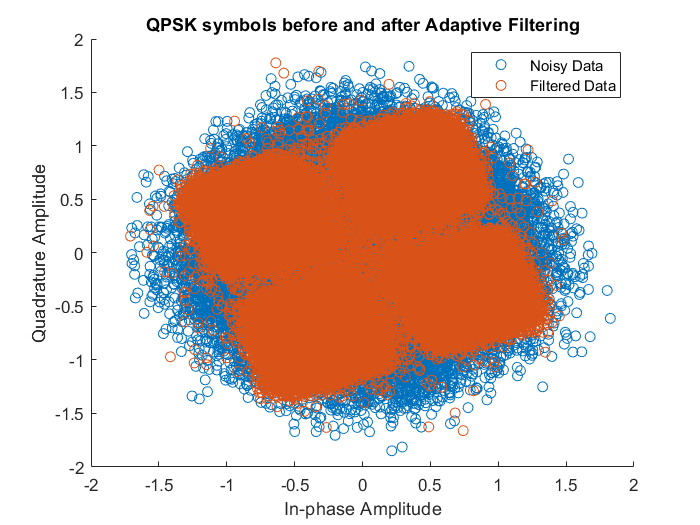

x = CD_qpsk.'; %Received Input

h_taps = 17; %Small Value, power of 2

h = zeros(h_taps,1);
e = zeros(h_taps,1);
y = zeros('like',x);

h(9) = 1;  
% Train symbols to get h
training_size = num_samples;
mu = 0.0022;

%%% Update every second sample instead of every sample

for i = h_taps:training_size
    
    temp = x(i:-1:i-h_taps+1) ; %From 17th down to 1st
    
    y(i) = h.' * temp;
    
    e(i) = 1 - abs(y(i))^2;
    
    h = h + 2*mu*e(i).*conj(temp)*y(i);
end    

figure
hold on
scatter(real(CD_qpsk),imag(CD_qpsk));
scatter(real(y),imag(y));
legend("Noisy Data","Filtered Data");
title("QPSK symbols before and after Adaptive Filtering");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

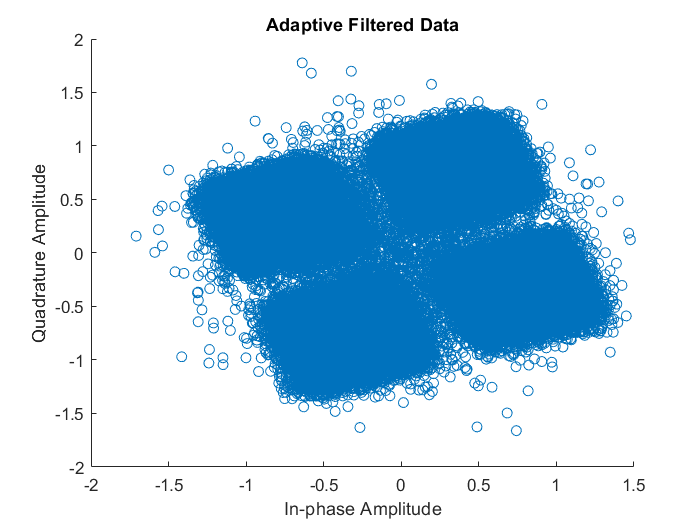


for i =  training_size+1 : num_samples
    
	temp = x(i:-1:i-h_taps+1) ;
    
    y(i) = h' * temp ;
    
    e(i) = 1 - abs(y(i))^2;
end


figure
scatter(real(y),imag(y));
title("Adaptive Filtered Data");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

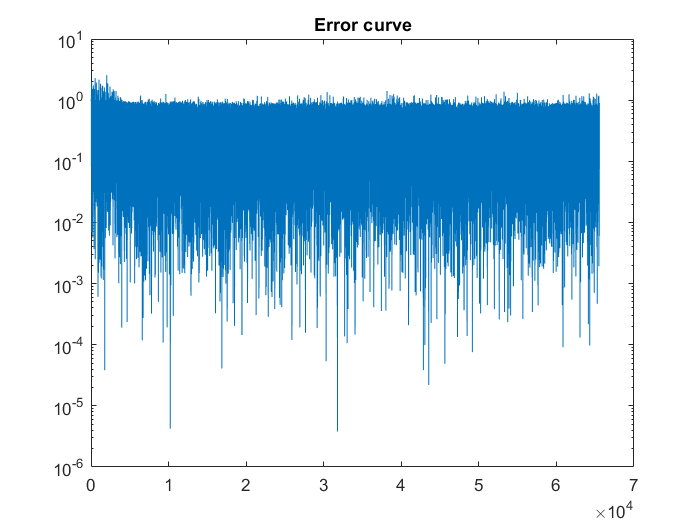


figure
semilogy((abs(e))) ;
title('Error curve');

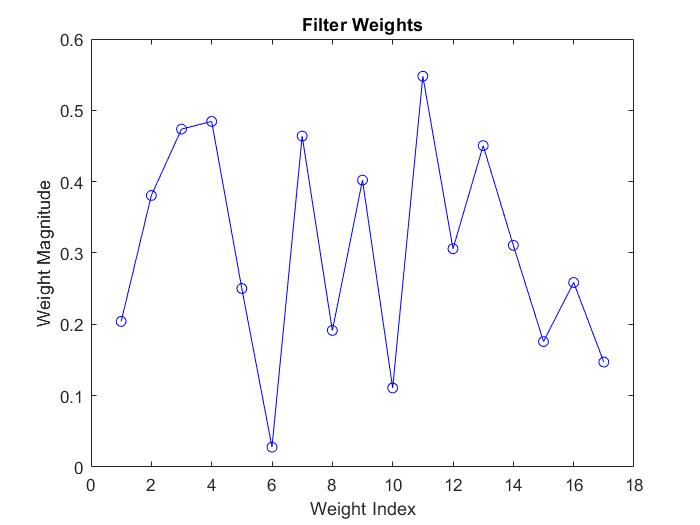


figure
plot(abs(h),'bo-');
title("Filter Weights");
xlabel("Weight Index");
ylabel("Weight Magnitude");

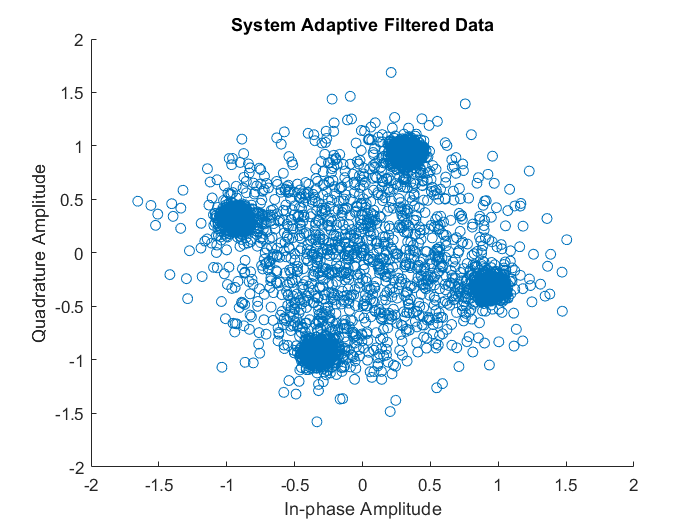


%%%%% System Object
lineq = comm.LinearEqualizer("Algorithm","CMA","InputSamplesPerSymbol",2,"StepSize",0.01,"NumTaps",17,"ReferenceTap",9);
[Filtered_qpsk,errors,weights] = lineq(CD_qpsk.');

figure
scatter(real(Filtered_qpsk),imag(Filtered_qpsk));
title("System Adaptive Filtered Data");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

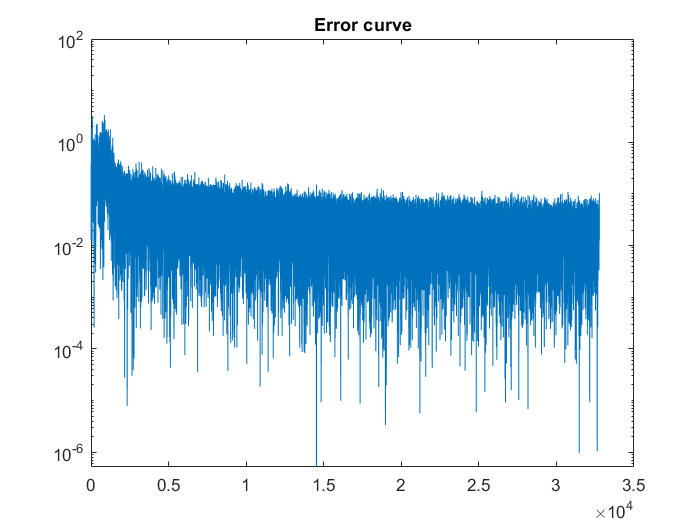


figure
semilogy((abs(errors))) ;
title('Error curve');

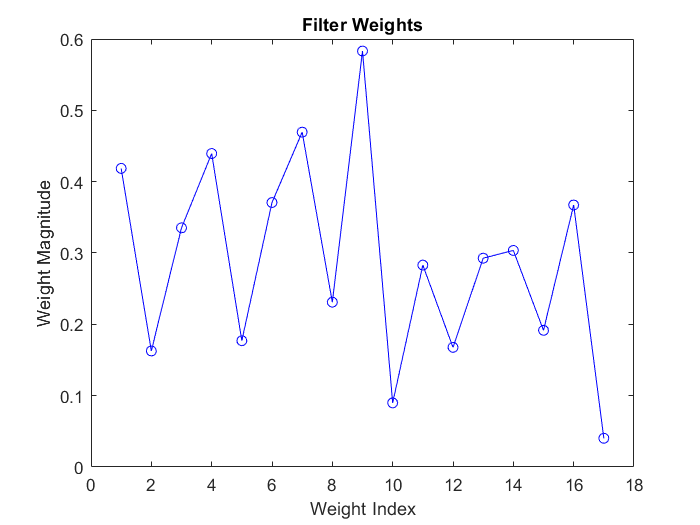


figure
plot(abs(weights),'bo-');
title("Filter Weights");
xlabel("Weight Index");
ylabel("Weight Magnitude");

Adaptive Attempt 2

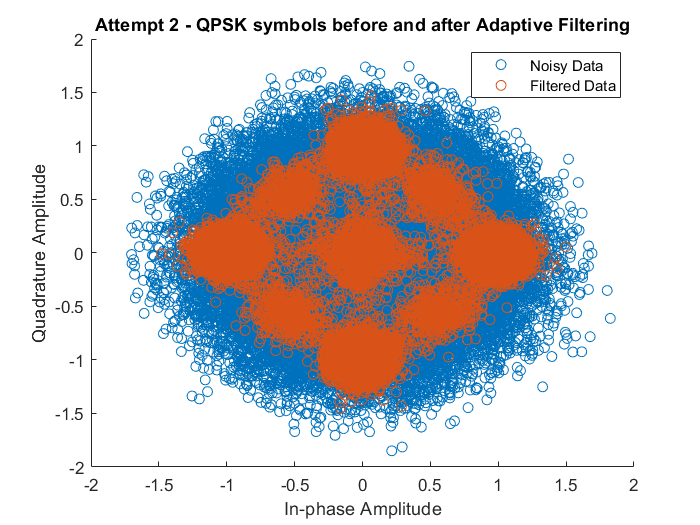


CD_Static_Filter = CD_Filter(symbol_rate,D,z,lambda);

Filtered_CD_qpsk = fftfilt(CD_Static_Filter,CD_qpsk);

x2 = Filtered_CD_qpsk.';

h_taps = 17;
mu2 = 0.002;
u2 = zeros(h_taps,1);
h2 = zeros(h_taps,1);
h2(floor(h_taps/2)+1) = 1;

length_after_eq = length(x)/upsampling;

y2 = zeros([length_after_eq 1],'like', x);
e2 = zeros([length_after_eq 1],'like', x);


for i = 1:length_after_eq
    
    %update tap delay line
    for j = h_taps:-1:upsampling+1
        u2(j) = u2(j-upsampling);
    end    
    
    for k=1:upsampling
        u2(k,1) = x2((i-1)*upsampling+k,1);
    end
        
    %Filter
    temp = h2' * u2;
    
    % Error Signal
    e_datapoint = temp * (1 - abs(temp).^2);
    
    h2 = h2 + mu2*u2*conj(e_datapoint);
    
    y2(i,1) = temp;
    e2(i,1) = e_datapoint;
    
end    

figure
hold on
scatter(real(CD_qpsk),imag(CD_qpsk));
scatter(real(y2),imag(y2));
legend("Noisy Data","Filtered Data");
title("Attempt 2 - QPSK symbols before and after Adaptive Filtering");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

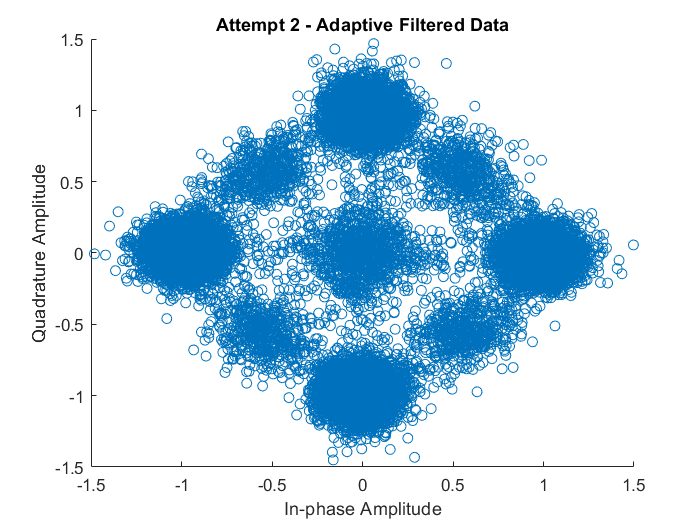


figure
scatter(real(y2),imag(y2));
title("Attempt 2 - Adaptive Filtered Data");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

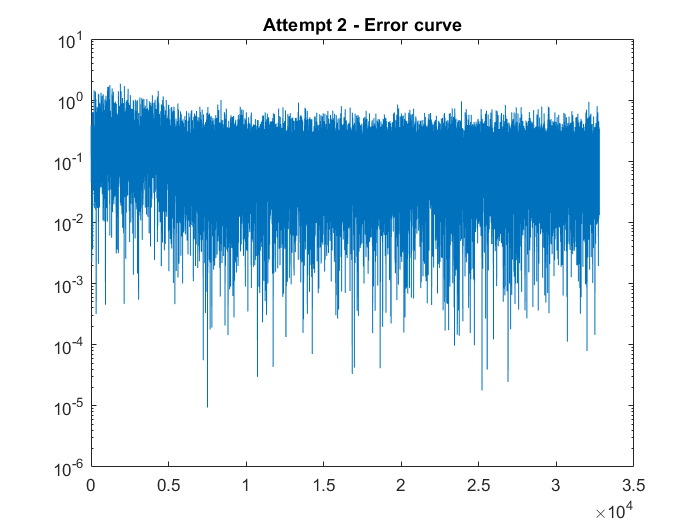


figure
semilogy((abs(e2))) ;
title('Attempt 2 - Error curve');

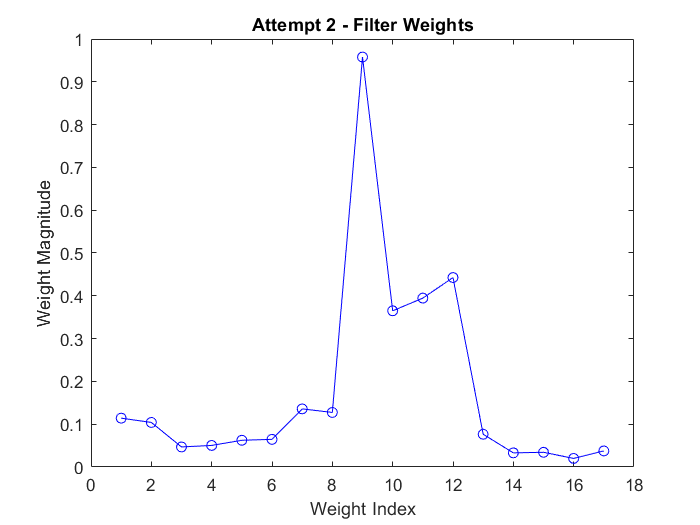


figure
plot(abs(h2),'bo-');
title("Attempt 2 - Filter Weights");
xlabel("Weight Index");
ylabel("Weight Magnitude");

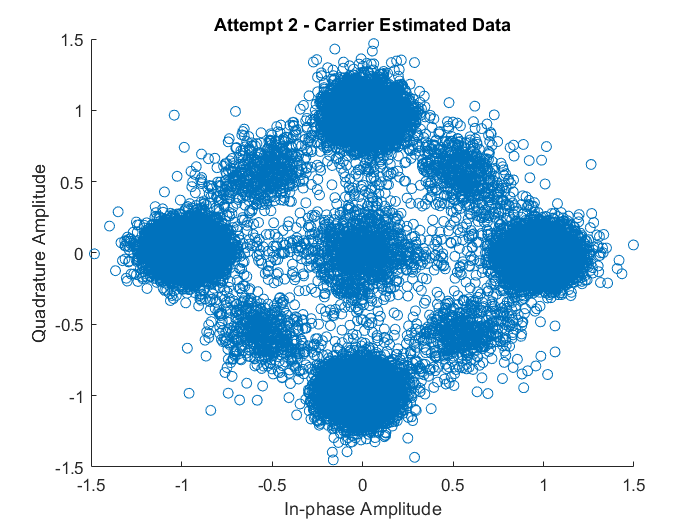


attempt2 = y2;


%Attempt to find the mean angle in chunks
raised_phase_qpsk = attempt2.^4;

chunk_size = [64,1];
mean_filter_fun = @(theBlockStructure) mean2(theBlockStructure.data(:));
qpsk_averages = blockproc(raised_phase_qpsk,chunk_size,mean_filter_fun);
phase_estimates = 1/4.*angle(qpsk_averages);

%phase_estimate_qpsk = 1/4.*angle(mean(raised_phase_qpsk));
multiple = length(attempt2) - mod(length(attempt2),chunk_size(1));
reshaped = reshape(attempt2(1:multiple),chunk_size(1),[]);
leftover = attempt2(multiple+1:end);
leftover = padarray(leftover,[chunk_size(1)-length(leftover) 0],0,'post');

combined = [reshaped leftover];

for iter=1:size(reshaped,2)
    combined(iter) = combined(iter).*exp(1j*pi/4-1j*phase_estimates(iter)+3j*pi/2);
end

attempt2_phase_compensated = reshape(combined,[],1);

attempt2 = attempt2_phase_compensated(1:length(attempt2));

figure
scatter(real(attempt2),imag(attempt2));
title("Attempt 2 - Carrier Estimated Data");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

## Adaptive Equalisation (Attempt CMA algorithm) 16-QAM

% x = upsampled_qam16.'; %Received Input
% 
% h_taps = 17; %Small Value, power of 2
% 
% h = zeros(h_taps,1);
% e = zeros(h_taps,1);
% y = zeros('like',x);
% 
% h(9) = 1;  
% % Train symbols to get h
% training_size = 2000;
% mu = 0.002;
% 
% for i = h_taps:training_size
%     
%     temp = x(i:-1:i-h_taps+1) ; %From 8th down to 1st
%     
%     y(i) = h.' * temp;
%     
%     e(i) = 1 - abs(y(i))^2;
%     
%     h = h + 2*mu*e(i)*conj(temp)*y(i);
% end    
% 
% figure
% hold on
% scatter(real(upsampled_qpsk),imag(upsampled_qpsk));
% scatter(real(y),imag(y));
% legend("Noisy Data","Filtered Data");
% title("QPSK symbols before and after Adaptive Filtering");
% ylabel("Quadrature Amplitude");
% xlabel("In-phase Amplitude");
% 
% for i =  training_size+1 : num_samples
%     
% 	temp = x(i:-1:i-h_taps+1) ;
%     
%     y(i) = h' * temp ;
%     
%     e(i) = 1 - abs(y(i))^2;
% end
% 
% 
% figure
% scatter(real(y),imag(y));
% title("Adaptive Filtered Data");
% ylabel("Quadrature Amplitude");
% xlabel("In-phase Amplitude");
% 
% figure
% semilogy((abs(e))) ;
% title('Error curve');
% 
% figure
% plot(abs(h),'bo-');
% title("Filter Weights");
% xlabel("Weight Index");
% ylabel("Weight Magnitude");


downsampled_qpsk = DPS_filter(y.').';

if mean(abs(downsampled_qpsk(2:2:end)).^2)>mean(abs(downsampled_qpsk(1:2:end)).^2)
   downsampled_qpsk=downsampled_qpsk(2:2:end);
else
   downsampled_qpsk=downsampled_qpsk(1:2:end);
end
    
demoded_qpsk = pskdemod(downsampled_qpsk,4,pi/4,'gray');

lag = finddelay(symbols_q,demoded_qpsk);
"Personal Filter"

ans = "Personal Filter"

[ERRORS1,BER1] = biterr(symbols_q(1:end-lag),demoded_qpsk(1+lag:end))

ERRORS1 = 3616

BER1 = 0.0552



%%%% System Object Comparison
DPS_filter2 = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",32,"InputSamplesPerSymbol",1,"DecimationFactor",1);

downsampled_qpsk = DPS_filter2(Filtered_qpsk).';

% if mean(abs(downsampled_qpsk(2:2:end)).^2)>mean(abs(downsampled_qpsk(1:2:end)).^2)
%    downsampled_qpsk=downsampled_qpsk(2:2:end);
% else
%    downsampled_qpsk=downsampled_qpsk(1:2:end);
% end
    
demoded_qpsk = pskdemod(downsampled_qpsk,4,pi/4,'gray');
"System Filter"

ans = "System Filter"

lag = finddelay(symbols_q,demoded_qpsk);
[ERRORS_SYS,BER_SYS] = biterr(symbols_q(1:end-lag),demoded_qpsk(1+lag:end))

ERRORS_SYS = 723

BER_SYS = 0.0110





attempt2_matched = DPS_filter2(attempt2).';
attempt2_demoded = pskdemod(attempt2_matched,4,pi/4,'gray');
"Attempt 2"

ans = "Attempt 2"

lag = finddelay(symbols_q,attempt2_demoded);
[ERRORS2,BER2] = biterr(symbols_q(1:end-lag),attempt2_demoded(1+lag:end))

ERRORS2 = 14723

BER2 = 0.2250